# The WIM method for CICE6.

As CICE6 does not include wave propagation through ice, for wave forcing, we must attach a *waves-in-ice module* (WIM). This particular WIM has the following method:

- Take the signfiicant wave height, peak period and mean wave direction for the most northern ice-free cell.

- Apply a directional filter such that waves only propagate along longitudinal lines.

- Define the wave spectrum using a Bretschneider spectrum at this ice-free cell.

- Propagate through the ice (towards Antarctica) using the attenuation coefficent from Meylan et al. (2014).

- Calculate the signfiicant wave height and peak period for the propagated waves and feed this into CICE6.

% Preamble
clc
clear all
close all
addpath functions
%cd .. % Move up one directory
day = 9;
month = 1;
year = 2005;
sector = "SA";
if day < 9
    date = sprintf('%d-0%d-0%d', year, month, day);
else
    date = sprintf('%d-0%d-%d', year, month, day);
end
case_name = '31freq';
ticker = 1;
SIC = 0.15; 
filename = "/Volumes/NoahDay5TB/cases/31freq/history/iceh.2008-07-30.nc";%/Volumes/NoahDay5TB/cases/forcingnowaves/history/iceh.2005-07.nc";%"prra_input4MIPs_atmosphericState_OMIP_MRI-JRA55-do-1-5-0_gr_196201010130-196212312230.nc";
%strcat('cases/',case_name,"/history/iceh.",date,".nc");
% '/Users/noahday/Gadi/2010/JRA55_03hr_forcing_2010.nc';%'grid/gridded_ww3.glob_24m.200501.nc'; 
%filename = 'DATA/CESM/MONTHLY/ocean_forcing_clim_2D_gx1.20210330.nc';
% Read the header
ncdisp(filename)

Source:
           /Volumes/NoahDay5TB/cases/31freq/history/iceh.2008-07-30.nc
Format:
           classic
Global Attributes:
           title       = 'sea ice model output for CICE'
           contents    = 'Diagnostic and Prognostic Variables'
           source      = 'Los Alamos Sea Ice Model, CICE_6.2.0'
           comment     = 'This year has 366 days'
           comment2    = 'File written on model date 20080731'
           comment3    = 'seconds elapsed into model date:      0'
           conventions = 'CF-1.0'
           history     = 'This dataset was created on 2022-05-10 at 18:12:12.2'
           io_flavor   = 'io_netcdf'
Dimensions:
           d2        = 2
           ni        = 320
           nj        = 384
           nc        = 5
           nkice     = 7
           nksnow    = 1
           nkbio     = 3
           nkaer     = 5
           time      = 1     (UNLIMITED)
           nvertices = 4
           nf        = 16
Variables:
    time         
           Size:       

sector = "SH";
grid = 'gx1';
[lat,lon] = grid_read(grid);

%% Finding the ice edge
aice_data = data_format_sector(filename,"aice",sector);
[lat_ice_edge, lon_ice_edge] = find_ice_edge(aice_data,SIC,sector,lat,lon);

 
conFigure(11,1)
f = figure;
[p,a] = map_plot(aice_data,"aice","SH");

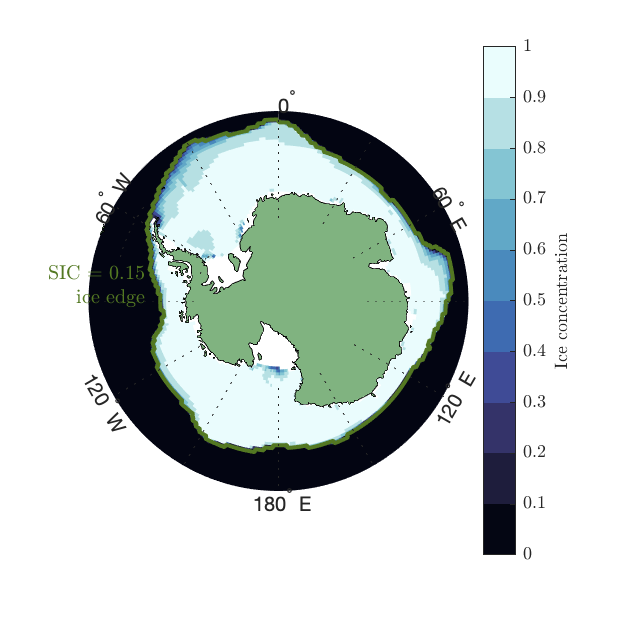

plotm(lat_ice_edge,lon_ice_edge,'-','color',0.7*[0.4660 0.6740 0.1880],'LineWidth',2) % Dark green
t = textm(lat_ice_edge(20)-5,lon_ice_edge(300),sprintf('SIC = %g\n ice edge',SIC),'HorizontalAlignment','right');
t.Color = 0.7*[0.4660 0.6740 0.1880];
%s = scaleruler
% setm(handlem('scaleruler'), ...
%     'XLoc',0.3, ... '
%     'YLoc',-0.52, ...
%     'TickDir','down', ...
%     'MajorTick',0:1000:1000, ...
%     'MinorTick',0:500:500, ...
%     'MajorTickLength',km2nm(150),...
%     'MinorTickLength',km2nm(150))

a.Label.String = "Ice concentration";
a.Label.Interpreter = "latex";
cmocean('ice',10)

%exportgraphics(f,'aice.pdf','ContentType','vector')


% Take the wave data from CAWCR for these cells
filename = "/Users/a1724548/GitHub/cice-dirs/input/CICE_data/forcing/gx1/CAWCR/MONTHLY/2005/ww3_200501.nc";
ncdisp(filename)

Source:
           /Users/a1724548/GitHub/cice-dirs/input/CICE_data/forcing/gx1/CAWCR/MONTHLY/2005/ww3_200501.nc
Format:
           classic
Global Attributes:
           CDI                   = 'Climate Data Interface version 1.9.10 (https://mpimet.mpg.de/cdi)'
           Conventions           = 'CF-1.0'
           product_name          = 'ww3.glob_24m.200501.nc'
           area                  = 'Global 0.4 deg wave grid'
           latitude_resolution   = '   0.4000000'
           longitude_resolution  = '   0.4000000'
           southernmost_latitude = '-78.0000000'
           northernmost_latitude = '78.0000000'
           westernmost_longitude = '0.0000000'
           easternmost_longitude = '359.6000061'
           minimum_altitude      = '-12000 m'
           maximum_altitude      = '9000 m'
           altitude_resolution   = 'n/a'
           start_date            = '2005-01-01T00:00:00Z'
           stop_date             = '2005-01-31T23:00:00Z'
           date_created         

lat = ncread(filename,"TLAT");
lon = ncread(filename,"TLON");
mwd_data = ncread(filename,"dir");
fp_data = ncread(filename,"fp");
hs_data = ncread(filename,"hs");

% Plot the wave stats
conFigure(11,1)
f = figure;
w = worldmap('world');
    axesm eqaazim; %, eqaazim wetch eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-55]);
    setm(w, 'maplonlimit', [-180,-55]);

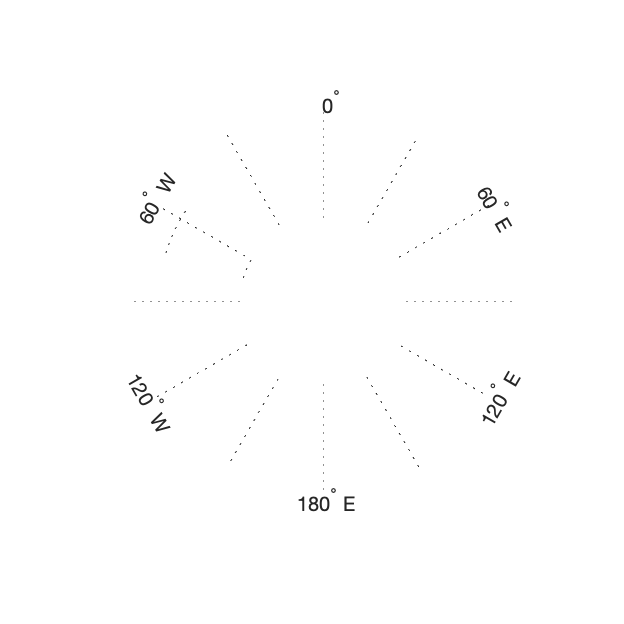

    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'mlinelimit', [-75 -55]);
    setm(w, 'plinelimit', [-75 -55]);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'off');
    setm(w, 'labelrotation', 'on')

    pcolorm(lat,lon,hs_data)

Error using SURFACEM
Expected LAT to be one of these types:

double

Instead its type was single.

Error in surfacem>parseInputs (line 128)
validateattributes(lat, {'double'}, {'2d'}, 'SURFACEM', 'LAT')

Error in surfacem (line 70)
[lat, lon, alt, grid, pvPairs] = parseInputs(varargin{:});

Erro

    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    a = colorbar;
    a.TickLabelInterpreter = 'latex';
    a.Label.Interpreter = 'latex';

% Plot what the Bretschneider spectrum may look like




% Plot transect of attenuation




% Plot the map of the propagated waves through ice 